*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 4 : Plug a custom scheduler into the 5G network model**

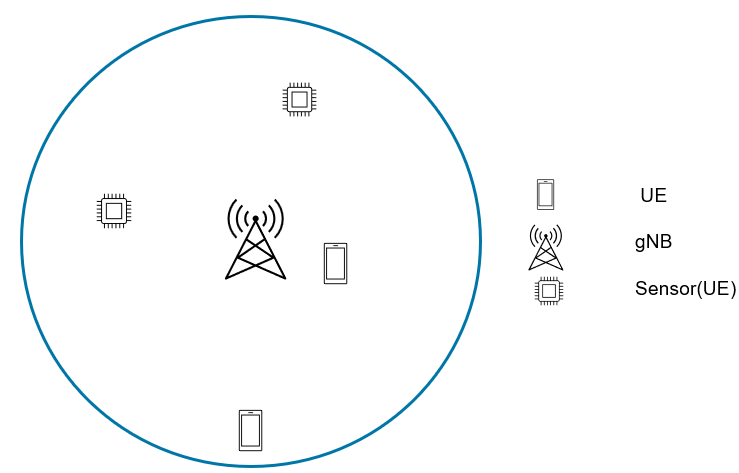

This exercise shows how to create and plug a custom resource-scheduling strategy in a 5G network. The goals are:

- Introduce custom traffic patterns to selected 5G nodes.

- Prioritize these nodes during resource scheduling using a custom scheduling algorithm.

- Visualize and quantify the impact of the custom scheduler  

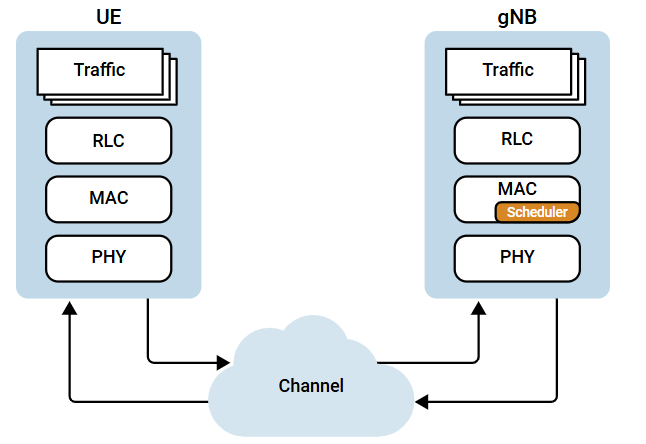

Check if the Communications Toolbox™ Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck

Create a wireless network simulator.

rng("default")           % Reset the random number generator
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities

numFrameSimulation = 100; % Simulation time in terms of number of 10 ms frames
simulationTime = numFrameSimulation*0.01 % Simulation Time in seconds

simulationTime = 1

networkSimulator = wirelessNetworkSimulator.init;

#### Create a gNB node 

Time: 0.020000 s - Generated a periodic packet_1 of size 30 bytes
Time: 0.040000 s - Generated a periodic packet_2 of size 30 bytes
Time: 0.060000 s - Generated a periodic packet_3 of size 30 bytes
Time: 0.080000 s - Generated a periodic packet_4 of size 30 bytes
Time: 0.100000 s - Generated a periodic packet_5 of size 30 bytes
Time: 0.120000 s - Generated a periodic packet_6 of size 30 bytes
Time: 0.140000 s - Generated a periodic packet_7 of size 30 bytes
Time: 0.160000 s - Generated a periodic packet_8 of size 30 bytes
Time: 0.180000 s - Generated a periodic packet_9 of size 30 bytes
Time: 0.200000 s - Generated a periodic packet_10 of size 30 bytes
Time: 0.220000 s - Generated a periodic packet_11 of size 30 bytes
Time: 0.240000 s - Generated a periodic packet_12 of size 30 bytes
Time: 0.260000 s - Generated a periodic packet_13 of size 30 bytes
Time: 0.280000 s - Generated a periodic packet_14 of size 30 bytes
Time: 0.300000 s - Generated a periodic packet_15 of size 30 bytes
Time

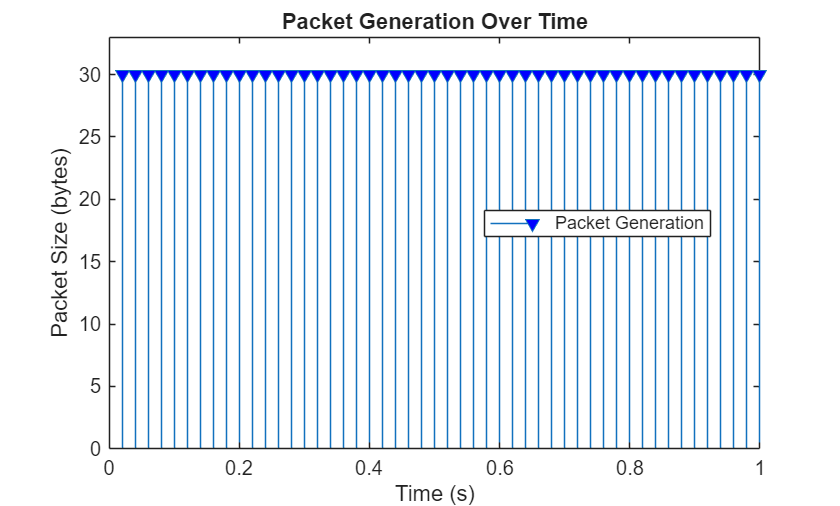

gNB = nrGNB(Position=[0 0 10], ...
    CarrierFrequency=2.6e9, ...
    ChannelBandwidth=5e6, ...

    SubcarrierSpacing=15e3, ...
    ReceiveGain=11, ...
    NumTransmitAntennas=1, ...
    NumReceiveAntennas=1, ...
    SRSPeriodicityUE=40);

#### Custom scheduler 

- The **New Radio (NR) scheduler** is a crucial component of the 5G NR protocol stack.

- It efficiently allocates radio resources to **user equipment (UE) nodes**.

- The scheduler resides in the **MAC layer** of the 5G protocol stack.

#### Strategy Description

Scheduling of High-Priority UE nodes (priority 1):

-     The strategy allots a predefined, fixed number of RBs to each eligible high-priority UE.  

-     If the strategy cannot serve all high-priority UE nodes with the required fixed number of RBs, 

-     Then it schedules UE nodes from a randomly selected subset of high-priority UE nodes in the slot.

Scheduling of Low-Priority UE nodes (priority 2):

-     After allocating RBs to high-priority UE nodes, the strategy distributes remaining RBs them equally among low-priority UEs 

RBsforHPUEs = 4; 
myScheduler = helperNRCustomSchedulingStrategy(NumRBHighPriority=RBsforHPUEs);
schedulerType = "Custom";
if strcmp(schedulerType,"Custom")

# Task #1/2 Configure the Scheduler at gNB

% Use configureScheduler() function 
% Hint: % Hint: Click the link below and see the "Syntax" section.
% Use the following argumnets 
% gNB
% Scheduler= myScheduler
% CSIMeasurementSignalDL="CSI-RS"
% ResourceAllocationType=1
% MaxNumUsersPerTTI =8

### [Help on sheduler configuration  ](https://www.mathworks.com/help/5g/ref/nrgnb.configurescheduler.html)

% <enter code below>   


else
    configureScheduler(gNB,Scheduler= schedulerType);
end

#### Create four UE nodes. Specify the name and the position of each UE node

numUEs = 4;
uePositions = [randi([0 250],numUEs,2) ones(numUEs,1)];
ueNames = ["HPUE-1","HPUE-2","UE-3","UE-4" ];
UEs = nrUE(Name=ueNames,Position=uePositions);

# Task #2/2 Configure a traffic model 

trafficType = "High Priority Traffic";
dataRate = 12; %in kbps
% Define traffic type
% Use networkTrafficOnOff() function to configure application layer traffic
% Write configuration in a variable named "ulApp_1"
% Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% OnTime = Inf
% OffTime = 0
% DataRate = dataRate
% PacketSize = 30
% GeneratePacket=true

% <enter code below>


plotTrafficPattern(simulationTime,ulApp_1);

Instances of periodic traffic: 

- Include sensor networks reporting at fixed intervals

- Heartbeat messages in network protocols

- Timed updates in control systems

ulApp_2 = networkTrafficOnOff(OnTime=Inf, ...
    DataRate=dataRate, ...
    PacketSize=30, ...
    GeneratePacket=true);

#### Connect the UE nodes to the gNB node and install traffic 

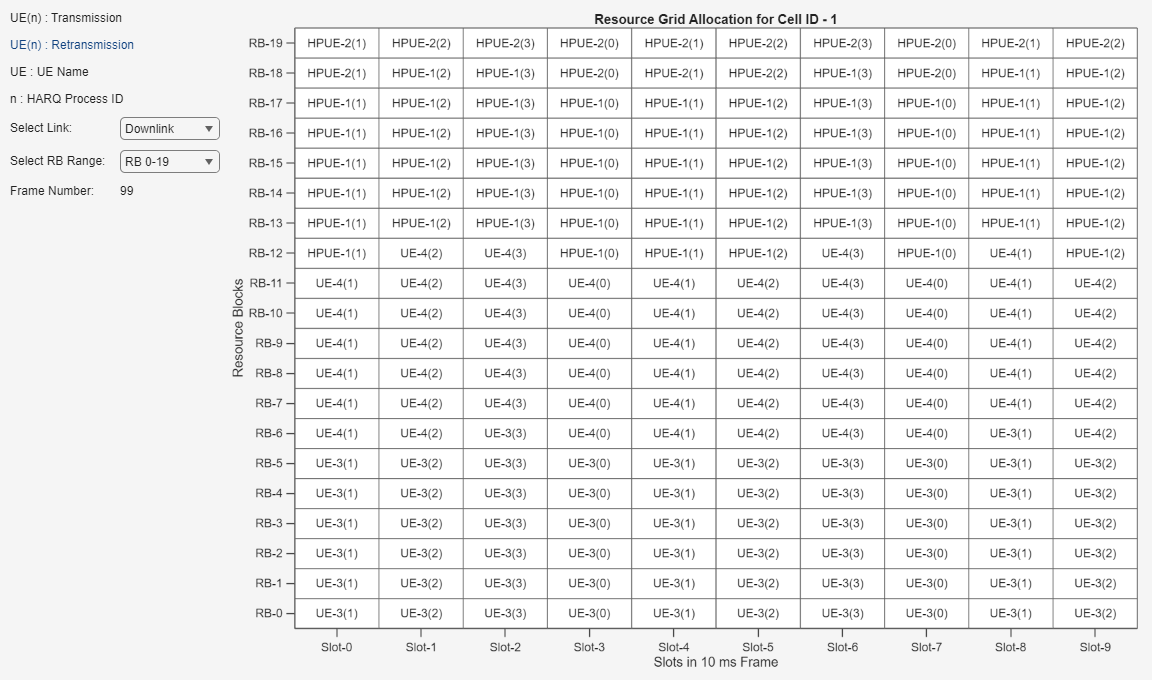

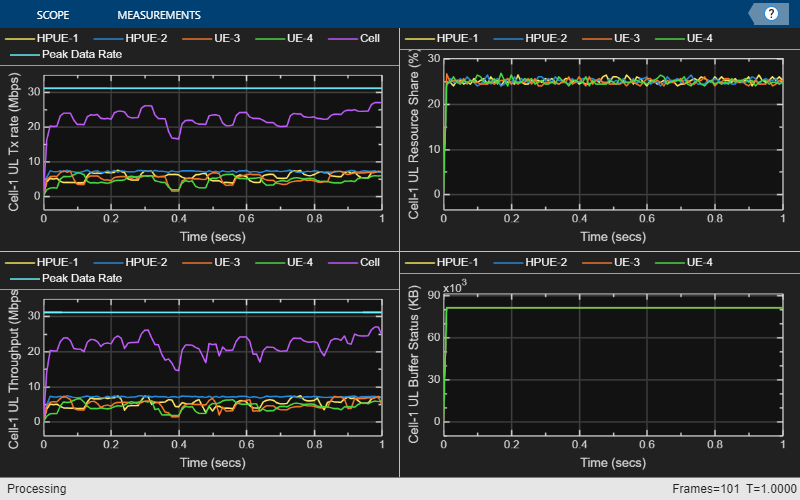

highPriorityUEs = [UEs(1), UEs(2)];

% Connect high-priority UE nodes
if (strcmp(trafficType,"High Priority Traffic"))
    connectUE(gNB,highPriorityUEs, CSIReportPeriodicity=10, CustomContext=struct("Priority",1), FullBufferTraffic="off");   
    addTrafficSource(UEs(1),ulApp_1);
    addTrafficSource(UEs(2),ulApp_2);
else
    connectUE(gNB,highPriorityUEs,CSIReportPeriodicity=10, CustomContext=struct("Priority",1),FullBufferTraffic="on");
end

lowPriorityUEs  = [UEs(3), UEs(4)];
% Connect low-priority UE nodes with full buffer traffic
connectUE(gNB,lowPriorityUEs,CSIReportPeriodicity=10,CustomContext=struct(Priority=2), FullBufferTraffic="on")

####  Add UEs and gNBs to network simulator

addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)

#### Use 3GPP TR 38.901 channel model for all links. You can also use free space path loss (FSPL) model.

channelModel = "3GPP TR 38.901";

if strcmp(channelModel,"3GPP TR 38.901")
    % Define scenario boundaries
    pos = [reshape([gNB.Position],3,[])];
    minX = min(pos(1,:));          % x-coordinate of the left edge of the scenario in meters
    minY = min(pos(2,:));          % y-coordinate of the bottom edge of the scenario in meters
    width = max(pos(1,:)) - minX;  % Width (right edge of the 2D scenario) in meters, given as maxX - minX
    height = max(pos(2,:)) - minY; % Height (top edge of the 2D scenario) in meters, given as maxY - minY
  
    % Create the channel model
    channel = h38901Channel(Scenario="UMa",ScenarioExtents=[minX minY width height]);
    % Add the channel model to the simulator
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Set up the logger and visualization 

% Create an object to log scheduler traces
simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UEs);
% Create an object for CQI and RB grid visualization
gridVisualizer = helperNRGridVisualizer(numFrameSimulation,gNB,UEs,ResourceGridVisualization=true,SchedulingLogger= simSchedulingLogger, CQIGridVisualization=false);
metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,RefreshRate=100, PlotSchedulerMetrics=true,PlotPhyMetrics=false, LinkDirection=1);

#### Run the simulation for the specified `numFrameSimulation` frames.

% Run the simulation
run(networkSimulator,simulationTime);



*Copyright 2021-2024 The MathWorks, Inc.*